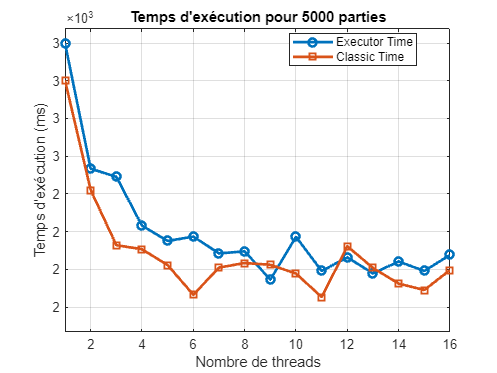

% Entrer le nom du fichier CSV manuellement
filename = "evaldata_multitache/threading_performance_5000parties";

% Lire les données du fichier CSV
data = readtable(filename);

% Extraire les colonnes pertinentes
nb_threads = data.nb_threads;
executor_time = data.executor_time_ms;
classic_time = data.classic_time_ms;

% Extraire le nombre de parties
nb_parties = data.nb_parties(1);

% Tracer les courbes de comparaison
figure;
plot(nb_threads, executor_time, '-o', 'LineWidth', 2, 'DisplayName', 'Executor Time');
hold on;
plot(nb_threads, classic_time, '-s', 'LineWidth', 2, 'DisplayName', 'Classic Time');
grid on;

% Ajouter des titres et des étiquettes
title(['Temps d''exécution pour ', num2str(nb_parties), ' parties']);
xlabel('Nombre de threads');
ylabel('Temps d''exécution (ms)');
legend('Location', 'best');

% Ajuster les axes pour plus de lisibilité
xlim([min(nb_threads) max(nb_threads)]);
ylim([min(min(executor_time), min(classic_time)) * 0.9, max(max(executor_time), max(classic_time)) * 1.1]);

% Forcer l'affichage en notation scientifique
ax = gca;
ax.YAxis.Exponent = 3;  % Force l'affichage avec e3 (10^3)
ytickformat('%,.0f');  % Garde le format classique sans décimales

% Ajouter une grille et tenir compte des deux tracés
hold off;
% Ajouter une grille et tenir compte des deux tracés
hold off;;

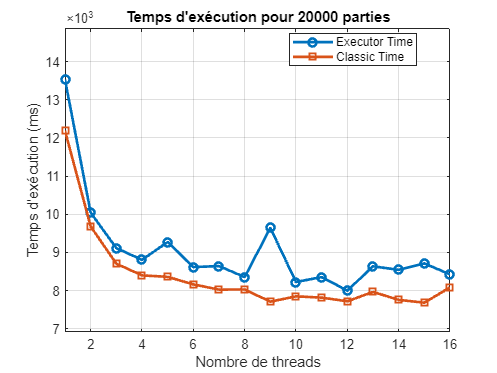

% Entrer le nom du fichier CSV manuellement
filename = "evaldata_multitache/threading_performance_20000parties";

% Lire les données du fichier CSV
data = readtable(filename);

% Extraire les colonnes pertinentes
nb_threads = data.nb_threads;
executor_time = data.executor_time_ms;
classic_time = data.classic_time_ms;

% Extraire le nombre de parties
nb_parties = data.nb_parties(1);

% Tracer les courbes de comparaison
figure;
plot(nb_threads, executor_time, '-o', 'LineWidth', 2, 'DisplayName', 'Executor Time');
hold on;
plot(nb_threads, classic_time, '-s', 'LineWidth', 2, 'DisplayName', 'Classic Time');
grid on;

% Ajouter des titres et des étiquettes
title(['Temps d''exécution pour ', num2str(nb_parties), ' parties']);
xlabel('Nombre de threads');
ylabel('Temps d''exécution (ms)');
legend('Location', 'best');

% Ajuster les axes pour plus de lisibilité
xlim([min(nb_threads) max(nb_threads)]);
ylim([min(min(executor_time), min(classic_time)) * 0.9, max(max(executor_time), max(classic_time)) * 1.1]);

% Forcer l'affichage en notation scientifique
ax = gca;
ax.YAxis.Exponent = 3;  % Force l'affichage avec e3 (10^3)
ytickformat('%,.0f');  % Garde le format classique sans décimales

% Ajouter une grille et tenir compte des deux tracés
hold off;
% Ajouter une grille et tenir compte des deux tracés
hold off;;

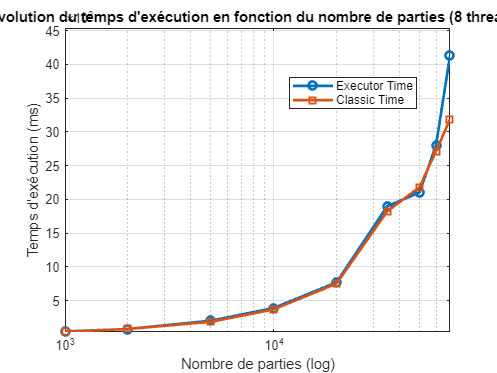

% Entrer le nom du fichier CSV manuellement
filename = "threading_performance_varied_parties.csv";

% Lire les données du fichier CSV
data = readtable(filename);

% Extraire les colonnes pertinentes
nb_parties = data.nb_parties;
executor_time = data.executor_time_ms;
classic_time = data.classic_time_ms;

% Tracer les courbes de comparaison (semi-log)
figure;
semilogx(nb_parties, executor_time, '-o', 'LineWidth', 2, 'DisplayName', 'Executor Time');
hold on;
semilogx(nb_parties, classic_time, '-s', 'LineWidth', 2, 'DisplayName', 'Classic Time');
grid on;

% Ajouter des titres et des étiquettes
title(['Évolution du temps d''exécution en fonction du nombre de parties (8 threads) ']);
xlabel('Nombre de parties (log)');
ylabel('Temps d''exécution (ms)');
legend('Location', 'best');

% Forcer une notation scientifique (si nécessaire)
ax = gca;
ax.YAxis.Exponent = 3;  % Force l'affichage avec e3
ytickformat('%,.0f');  % Affiche les ticks sans décimales

% Ajuster les axes pour plus de lisibilité
xlim([min(nb_parties) max(nb_parties)]);
ylim([min(min(executor_time), min(classic_time)) * 0.9, max(max(executor_time), max(classic_time)) * 1.1]);

hold off;

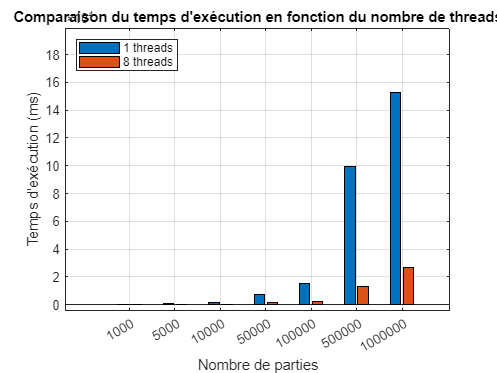

% Entrer le nom du fichier CSV manuellement
filename = "benchmark_1vs8_threads.csv";

% Lire les données du fichier CSV
data = readtable(filename);

% Extraire les colonnes pertinentes
nb_parties = data.nb_parties;
nb_threads = data.nb_threads;
temps_execution = data.temps_execution_ms;

% Restructurer les données pour le graphique en barres
parties_uniques = unique(nb_parties);
threads_uniques = unique(nb_threads);

% Créer une matrice pour stocker les temps d'exécution
temps_matrix = zeros(length(parties_uniques), length(threads_uniques));

for i = 1:length(parties_uniques)
    for j = 1:length(threads_uniques)
        temps_matrix(i, j) = temps_execution(nb_parties == parties_uniques(i) & nb_threads == threads_uniques(j));
    end
end

% Définir des abscisses personnalisées (avec des espacements)
x_positions = 1:length(parties_uniques);  % Espacement arbitraire
x_labels = arrayfun(@num2str, parties_uniques, 'UniformOutput', false);

% Tracer le graphique en barres
figure;
bar(x_positions, temps_matrix);
grid on;

% Ajouter des titres et des étiquettes
title('Comparaison du temps d''exécution en fonction du nombre de threads');
xlabel('Nombre de parties');
ylabel('Temps d''exécution (ms)');

% Personnaliser les ticks de l'axe des abscisses
set(gca, 'XTick', x_positions, 'XTickLabel', x_labels);

% Légende avec le nombre de threads
legend(arrayfun(@(x) sprintf('%d threads', x), threads_uniques, 'UniformOutput', false), 'Location', 'northwest');



% Ajuster les axes pour plus de clarté
xlim([0.5, length(parties_uniques) + 0.5]);  % Ajuste les marges pour les barres
ylim([0, max(temps_matrix(:)) * 1.1]);       % Laisser un peu d'espace au-dessus

% Entrer le nom du fichier CSV
filename = "performance_results.csv";

% Lire les données du fichier CSV
data = readtable(filename);

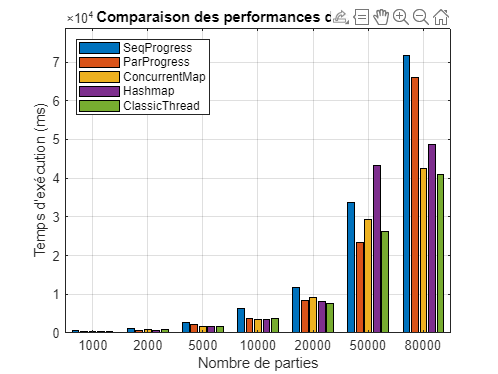


% Extraire les colonnes pertinentes
nb_parties = data.NbParties;
seq_progress = data.SeqProgress_ms_;
par_progress = data.ParProgress_ms_;
concurrent_map = data.ConcurrentMap_ms_;
no_sync = data.NoSync_ms_;
classic_thread = data.ClassicThread_ms_;

% Regrouper les données pour le graphique en barres
temps_matrix = [seq_progress, par_progress, concurrent_map, no_sync, classic_thread];

% Définir des abscisses personnalisées
x_positions = 1:length(nb_parties);
x_labels = arrayfun(@num2str, nb_parties, 'UniformOutput', false);

% Tracer le graphique en barres
figure;
bar(x_positions, temps_matrix, 'grouped');
grid on;

% Ajouter des titres et des étiquettes
title('Comparaison des performances des fonctions');
xlabel('Nombre de parties');
ylabel('Temps d''exécution (ms)');
set(gca, 'XTick', x_positions, 'XTickLabel', x_labels);

% Ajouter une légende
legend({'SeqProgress', 'ParProgress', 'ConcurrentMap', 'Hashmap', 'ClassicThread'}, ...
       'Location', 'northwest');

% Ajuster les axes
xlim([0.5, length(nb_parties) + 0.5]);
ylim([0, max(temps_matrix(:)) * 1.1]);